# **偶极子天线的仿真（天线工具箱仿真计算） **

**        Antenna Toolbox 提供了设计、分析单元线和阵列天线并使其可视化的功能和应用程序，可以使用具有参数化几何结构的预定义单元或任意平面单元设计独立的天线或创建阵列天线。**

- **定义天线**

**        下面例子中使用了 ant=dipole 这样的一条命令，用来定义一个偶极子天线 ant。事实上，在Antenna Toolbox 中还有很多类似的天线和天线阵可以直接定义，至于每个天线和天线阵的具体参数，可以参考 MATLAB R2023a 帮助文件查阅。**

ant=dipole;                                             %定义一个电偶极子天线

- **方向图仿真**

**        Antenna Toolbox 中的 pattern 函数是用来绘制天线或者天线阵在某个特定工作频率下的领射方向图，在 Antenna Toolbox 中一般默认其远场半径为波长的 100倍。**

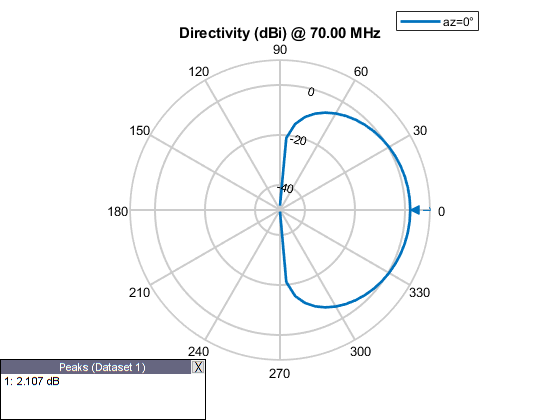

freq=70e6;
ele=-90:5:90;                                           %方位角
azi=-180:1:180;                                         %仰角
vertSlice=patternElevation(ant,freq,0,'Elevation',ele); %使用patternElevation函数创建2D图
theta=90-ele;
figure
patternElevation(ant,freq,0,'Elevation',ele);           %方位角为0°的仰角方向图

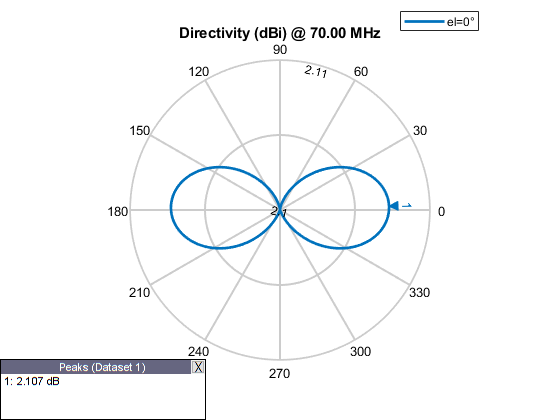

figure
patternAzimuth(ant,freq,0,'Azimuth',azi);               %仰角为0°的方位角方向图

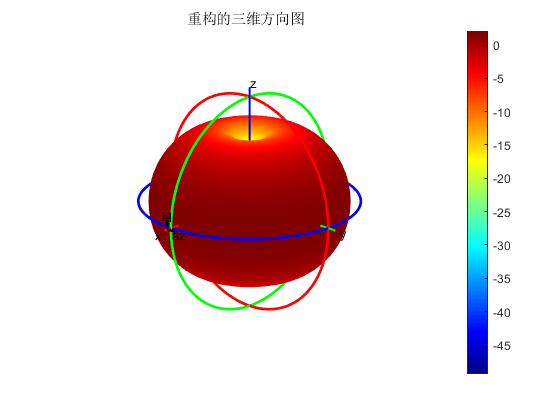

figure
patternFromSlices(vertSlice,theta);
title('重构的三维方向图');
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        理想的点源天线辐射没有方向性，在各方向上辐射强度相等，立体辐射图是一个球体。以理想的点源天线作为标准与实际天线进行比较，在相同的辐射功率下，某天线产生于某点的电场强度平方与理想的点源天线在同一点产生的电场强度的平方的比值称为该点的方向性系数。**

Directivity=pattern(ant,freq,0,90)                 %使用pattern函数还可以计算天线的方向性系数

Directivity = -48.2326

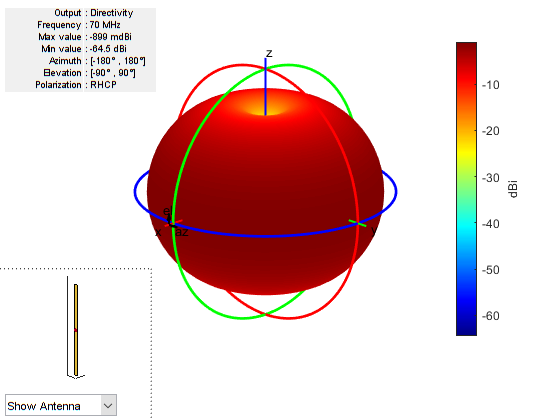

[E,H]=EHfields(ant,freq,[0;0;1]);                  %使用EHfields函数计算天线在空间一点的电场和磁场的x,y,z分量
figure
pattern(ant,freq,'Polarization','RHCP');           %使用pattern函数中的极化属性绘制天线的极化方式，反射天线和接收天线应具有相同的极化方式
                                                   %绘制偶极子天线的右旋圆极化方式的辐射方向图
title('右旋圆极化方式的偶极子天线的辐射方向图');

- **仿真计算天线轴比和输入阻抗**

**        一般情况下，任意极化波的瞬时电场矢量的端点轨迹为一个椭圆，椭圆的长轴和短轴之比称为天线的轴比AR，轴比是圆极化天线的一个重要的性能指标，代表圆极化的纯度。轴比为无穷大时，表示线极化，轴比为1时，表示圆极化。下面使用axialRatio函数计算天线的轴比，频率是70MHz，20是方位角，30是仰角**

ar=axialRatio(ant,freq,20,30)

ar = 56.8034

**        波瓣宽度是指天线的辐射方向图中低于3dB处所成夹角的大小，使用beamwidth函数计算天线的波瓣宽度**

[bw,angles]=beamwidth(ant,freq,0,1:1:360)  

bw =    80.0000
   80.0000


angles =    140   220
   320    40


**        使用 impedance 函数计算并绘制天线的输人阻抗。天线和馈线的连接处称为天线的输入端或馈电点。对于线天线来说，天线输人端的电压与电流的比值称为天线的输入阻抗。对于口面型天线，则常用馈线上电压驻波比来表示天线的阻抗特性。一般情况下，天线的输入阻抗是复数，实部称为输入电阻，以**$$$R_{i}$$$**表示；虚部称为输入电抗，以**$$$X_{i}$$$**表示。下面的语句用来绘制天线在某一频段的阻抗曲线**

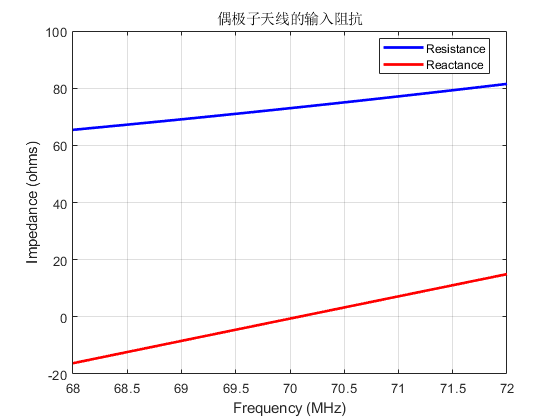

figure
impedance(ant,68e6:1e4:72e6);
title('偶极子天线的输入阻抗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真反射系数**

**        可以使用 sparameters 函数计算天线的反射系数**$$$s_{11}$$$**。反射系数为反射波振幅与入射波振幅之比，它是用来衡量阻抗匹配优劣的一个参数。一般地，阻抗匹配的优劣用4个参数来衡量，即反射系数、行波系数、驻波比和回波损耗，这 4 个参数之间有固定的数值关系，使用哪一个均出于习惯。**

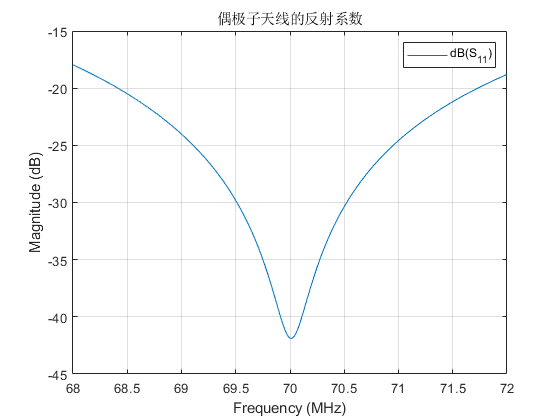

S=sparameters(ant,68e6:1e4:72e6,72);               %用sparameters函数计算天线的反射系数S11
figure
rfplot(S);
title('偶极子天线的反射系数');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真回波损耗**

**        回波损耗是反射系数绝对值的倒数，以分贝值表示，其值在0dB和无穷大之间，值越大表示匹配越好，0表示全反射，无穷大表示完全匹配，在移动通信系统中，一般要求回波损耗大于14dB。**

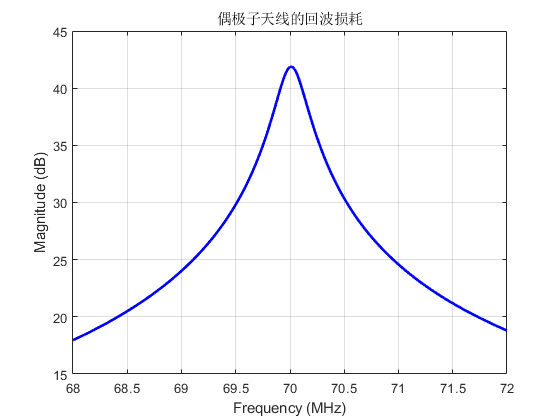

figure
returnLoss(ant,68e6:1e4:72e6,72);                  %用returnLoss函数计算并绘制天线的回波损耗
title('偶极子天线的回波损耗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真电压驻波比**

**        电磁波从甲介质传导到乙介质中，由于介质不同使得电磁波的能量会有一部分被反射，从而在甲区域形成行驻波，电压驻波比指的是行驻波的电压峰值与电压谷值之比，驻波比越大，反射功率越高，传输效率越低，无穷大时，为全反射，没有能量传输。**

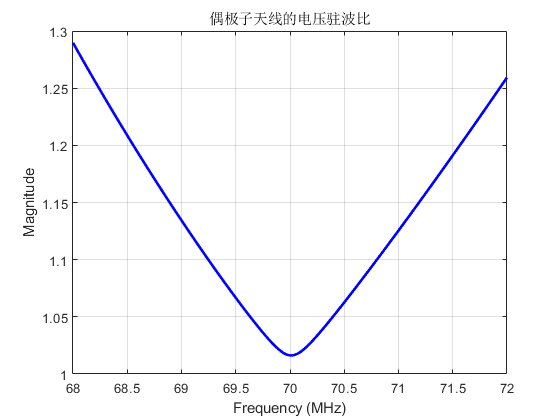

figure
vswr(ant,68e6:1e4:72e6,72);                        %用vswr函数计算并绘制天线的电压驻波比
title('偶极子天线的电压驻波比');
set(gcf,'Visible','on');   	    %强制图片弹出显示